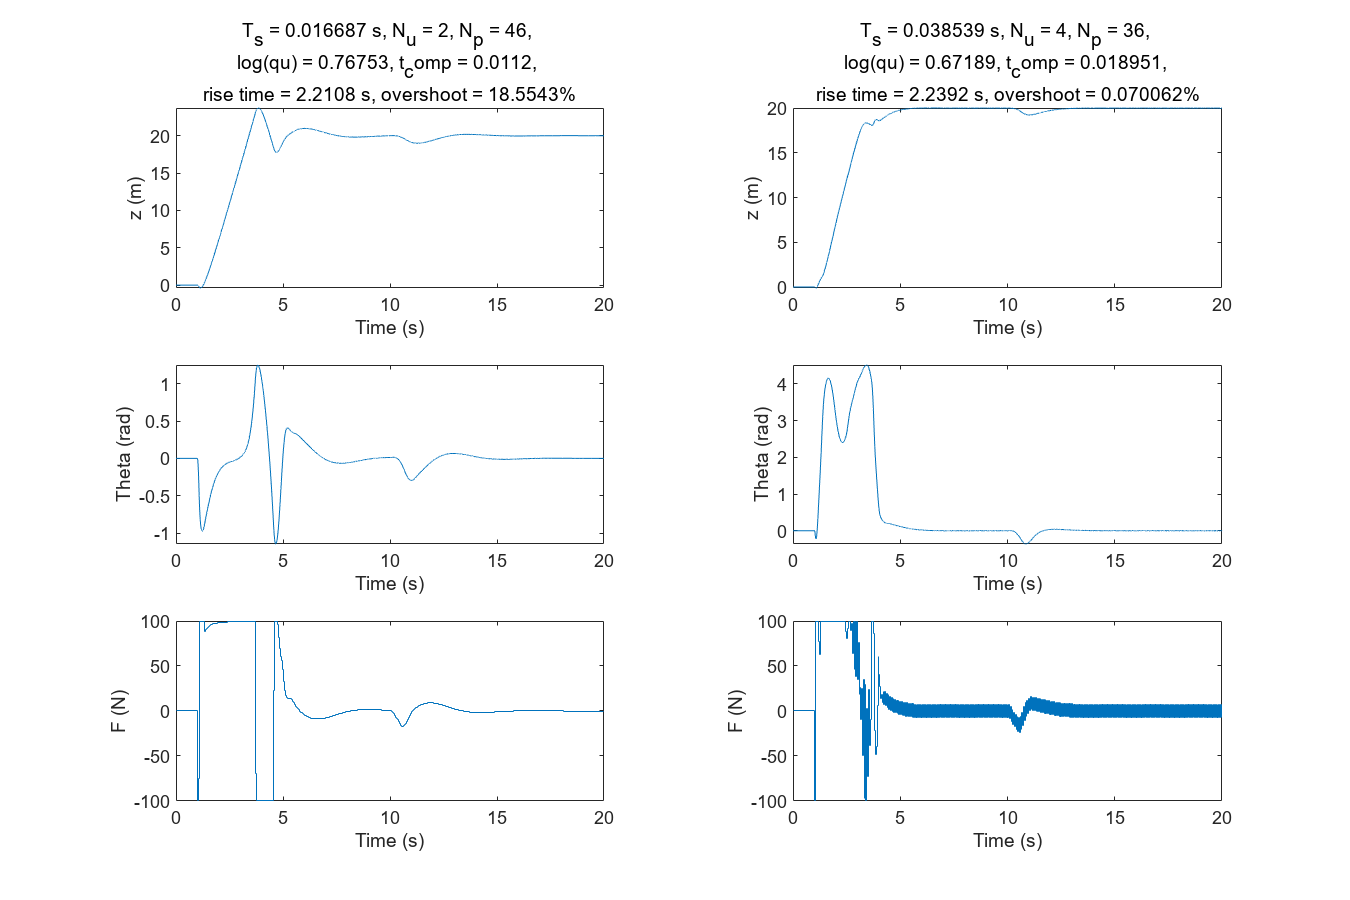

% the bounds of the tuning parameters 
lowerBound = [0.005 30 0.04 exp(-1)]';
upperBound = [0.05  60 0.3  exp(1)]';

% initialization of GLISp
opts = struct;
opts.maxevals = 50;  % maximum number of function evaluations
opts.delta = 0.6;        % weight on distance from previous samples
opts.nsamp = 10;     % number of initial samples
opts.useRBF = true;  % true = use RBFs, false = use IDW interpolation
opts.epsil = 1;

% opts.rbf=@(x1,x2) sqrt(1+epsil^2*sum((x1-x2).^2)); % multiquadratic
opts.rbf=@(x1,x2,epsil) 1/(1+epsil^2*sum((x1-x2).^2)); % inverse quadratic
opts.RBFcalibrate = true;
thetas=logspace(-1,1,11);
opts.thetas=thetas(1:end-1);
opts.acquisition_method = 1;
opts.scalevars = true;    % scale problem variables (default: true)
opts.globoptsol = 'pswarm';   % nonlinear solver used during acquisition.
                   % interfaced solvers are:
                   %    'direct' DIRECT from NLopt tool (nlopt.readthedocs.io)
                   %    'pswarm' PSWarm solver v2.1 (www.norg.uminho.pt/aivaz/pswarm/)
                   %    'tmw-pso' Particle Swarm Optimizer from MATLAB Global Optimization Toolbox
                   %    'tmw-ga' Genetic Algorithm from MATLAB Global Optimization Toolbox
f = @glisp_preftest_InverPen;
[xopt,out]=glisp(f,lowerBound,upperBound,opts)

function out = glisp_preftest_InverPen(a,b)     % displaying results for preference expression

out = figure;
set(out, 'Position', [100, 100, 900, 600]);
tiledlayout(3,2);

ax1 = nexttile(1);
ax2 = nexttile(3);
ax3 = nexttile(5);

InverPen_Run(a,ax1,ax2,ax3);

ax4 = nexttile(2);
ax5 = nexttile(4);
ax6 = nexttile(6);

InverPen_Run(b,ax4,ax5,ax6);

prompt =  "What is the preference between scenario 1 and 2? " + ...
    "\nIf 1 better than 2, key in -1; \nIf 1 as good as 2, key in 0; " + ...
    "\nIf 1 not worse than 2, key in 1.";
while true
    out = input(prompt);

    if out == 999
        error('Program terminated by user.');
    elseif out == -1 || out == 0 || out == 1
        if out == -1
            disp('The former better that the latter.');
        elseif out == 0
            disp('The former as good as the latter.');
        else
            disp('The former worse that the latter.');
        end
        break;

        % Continue with the rest of your program here
    else
        disp('Invalid input! Please try again.');
    end
end

        % out = input(prompt);
        % if out ~= -1 && out ~= 0 && out ~= 1
        %     error('Wrong preference number! ')
        % end
end

function InverPen_Run(Theta_,ax1,ax2,ax3)

% Setup for the tuning parameters
status = mpcverbosity('off');
Ts = Theta_(1);
Np = round(Theta_(2));
eps = Theta_(3);
Nu = round(eps*Theta_(2));
qu = Theta_(4);

mdlMPC = 'mpc_pendcartLTVMPC_modified';

% Obtaining the linearized discrete model and setup the MPC controller
x0 = zeros(4,1);
u0 = zeros(1,1);

[~,~,A,B,C,D] = pendulumCT(x0, u0);
plant = ss(A,B,C([1 3],:),D([1 3],:)); % position and angle

PredictionHorizon = Np;
ControlHorizon = Nu;

mpcobj = mpc(c2d(plant,Ts),Ts,PredictionHorizon,ControlHorizon);

mpcobj.MV.Min = -100;
mpcobj.MV.Max = 100;

% mpcobj.OV(2).Min = -pi/2;
% mpcobj.OV(2).Max = pi/2;

mpcobj.MV.ScaleFactor = 100;

mpcobj.Weights.MVRate = qu;

mpcobj.Weights.OV = [0.6 1.2];

setoutdist(mpcobj,'model',[0;tf(1)]);

setEstimator(mpcobj,'custom');

assignin('base', 'x0', x0);
assignin('base', 'u0', u0);
assignin('base', 'Ts', Ts);
assignin('base', 'PredictionHorizon', PredictionHorizon);
assignin('base', 'ControlHorizon', ControlHorizon);
assignin('base', 'mpcobj', mpcobj);

mpcverbosity(status);

t = tic;
sim(mdlMPC)
runtime = toc(t);
t_comp = 1.5*runtime/(20/Ts);

% Initialize simulation data for plotting
time = ScopeData.time;
X_result = ScopeData.signals(1).values;
Theta_result = ScopeData.signals(3).values;
F_result = ScopeData.signals(5).values;

finalVal = 20;
tol = finalVal*0.1;
risetime_index = find(abs(X_result - finalVal) <= tol, 1, 'first');
risetime = time(risetime_index)-1;
overshoot = ((max(X_result)-20)/20)*100;

% Plot the results
plot(ax1,time,X_result);
title(ax1, ['T_s = ',num2str(Ts),' s, ','N_u = ',num2str(Nu),', ','N_p = ',num2str(Np),', ', ...
            newline,'log(qu) = ',num2str(log(qu)),', ','t_comp = ',num2str(t_comp),', ', ...
            newline,'rise time = ',num2str(risetime),' s',', ','overshoot = ',num2str(overshoot),'%'])
xlabel(ax1, 'Time (s)')
ylabel(ax1, 'z (m)')

plot(ax2,time,Theta_result);
xlabel(ax2, 'Time (s)')
ylabel(ax2, 'Theta (rad)')

stairs(ax3,time,F_result);
xlabel(ax3, 'Time (s)')
ylabel(ax3, 'F (N)')
end